This script demonstates the clustering results of IDKC and GDKC on synthetic datasets. 

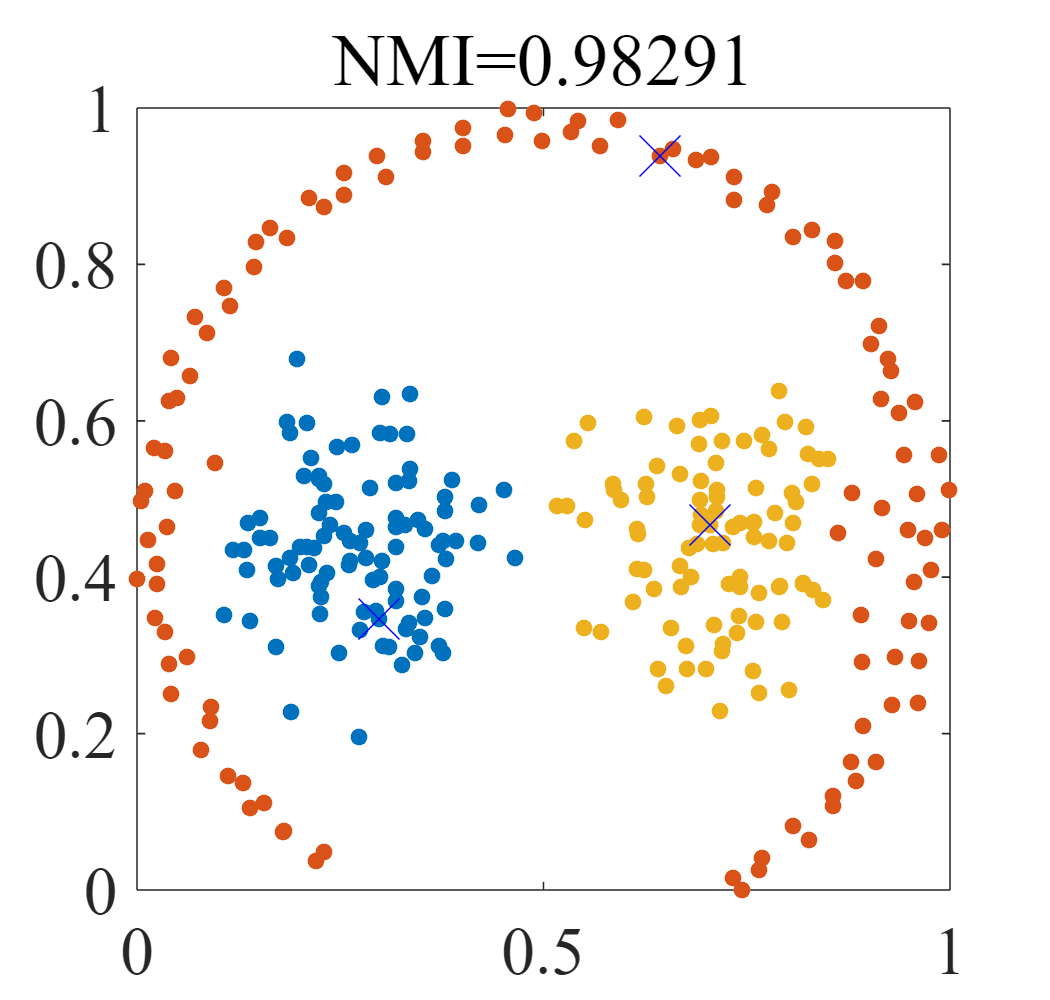

clear
close all
load('pathbased.mat') % load dateset

data = (data - min(data)).*((max(data) - min(data)).^-1);
data(isnan(data)) = 0.5; % data normalisation
k=size(unique(class),1);

v=0.9;
s=min(size(data,1),10000);
t=100;

psi=32; 
Kn=30; 
rng(368)

[ndata] = iNNEspace(data,data, psi, t); % Isolation features obtained with iNNE, can be changed to aNNE
[Tclass,Centre] =DKC(ndata,k,Kn,v,s); % IDKC
[NMI]=nmi(class,Tclass+1);  

visualResults(data,Tclass,Centre,NMI)

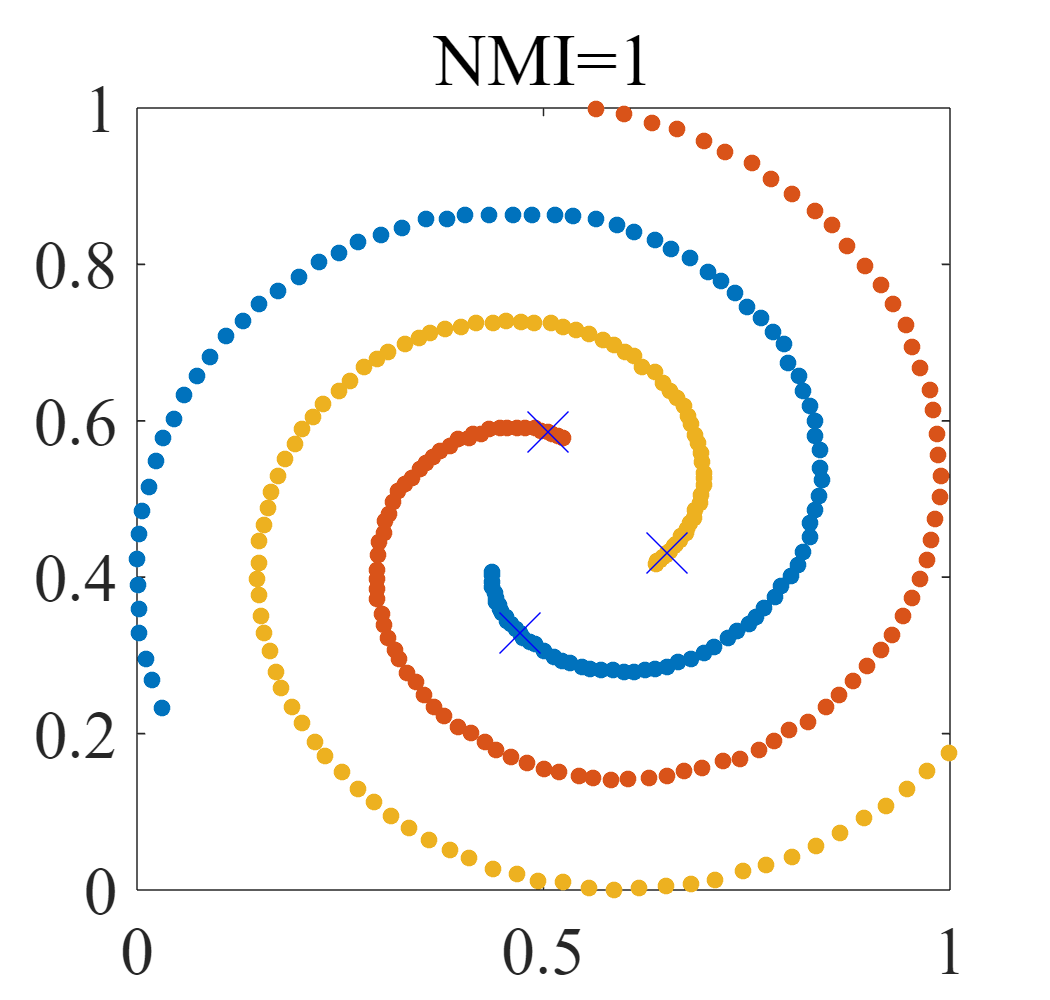

load('Spiral.mat') % load dateset

data = (data - min(data)).*((max(data) - min(data)).^-1);
data(isnan(data)) = 0.5; % data normalisation
k=size(unique(class),1);

v=0.9;
s=min(size(data,1),10000);
t=100;

psi=100;
Kn=24;
rng(1)

[ndata] = iNNEspace(data,data, psi, t);  
[Tclass,Centre] =DKC(ndata,k,Kn,v,s);
[NMI]=nmi(class,Tclass+1);

visualResults(data,Tclass,Centre,NMI)

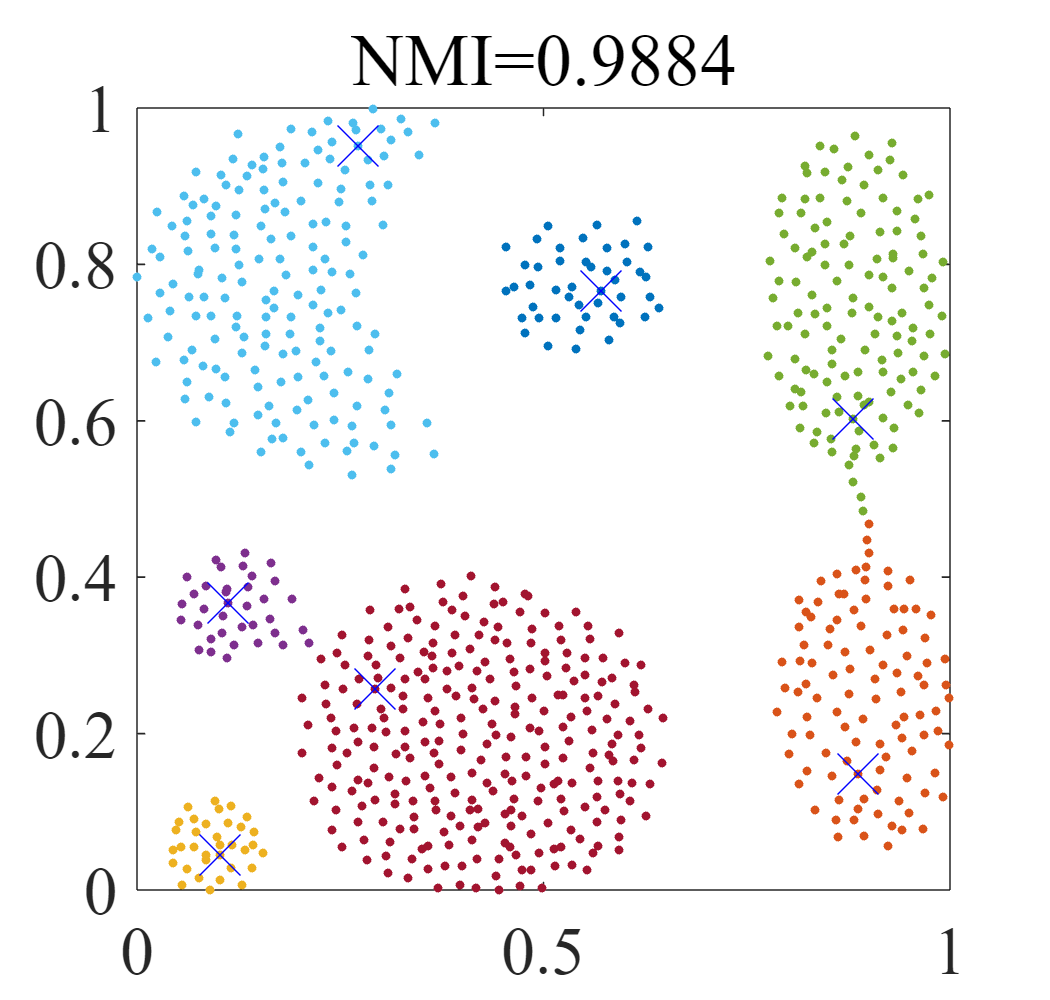

load('aggregation.mat') % load dateset

data = (data - min(data)).*((max(data) - min(data)).^-1);
data(isnan(data)) = 0.5; % data normalisation
k=size(unique(class),1);

v=0.9;
s=min(size(data,1),10000);
t=100;

psi=64;
Kn=276;
rng(31)

[ndata] = iNNEspace(data,data, psi, t);  
[Tclass,Centre] =DKC(ndata,k,Kn,v,s);
[NMI]=nmi(class,Tclass+1);

visualResults(data,Tclass,Centre,NMI)

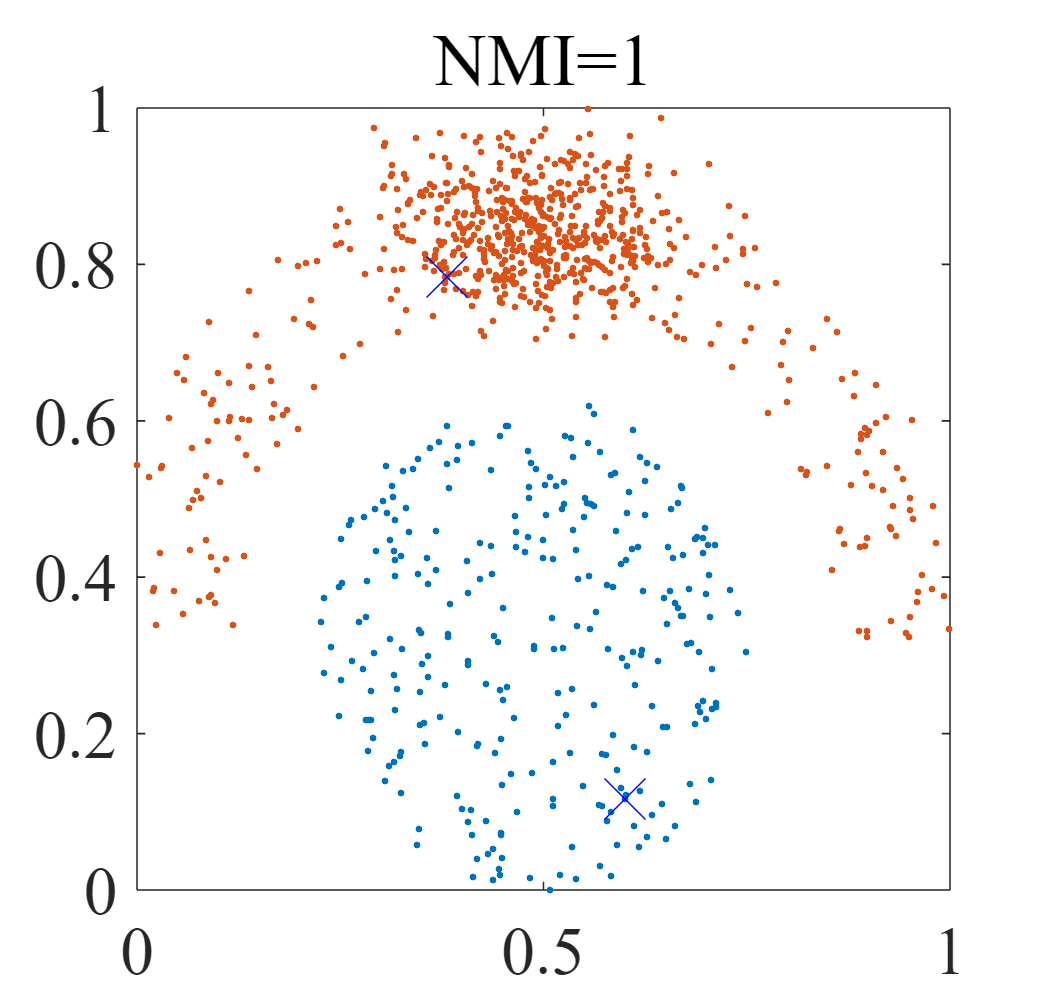

load('AC.mat') % load dateset

data = (data - min(data)).*((max(data) - min(data)).^-1);
data(isnan(data)) = 0.5; % data normalisation
k=size(unique(class),1);

v=0.9;
s=min(size(data,1),10000);
t=100;

psi=200;
Kn=101;
rng(6)

[ndata] = iNNEspace(data,data, psi, t);  
[Tclass,Centre] =DKC(ndata,k,Kn,v,s);
[NMI]=nmi(class,Tclass+1);


visualResults(data,Tclass,Centre,NMI)

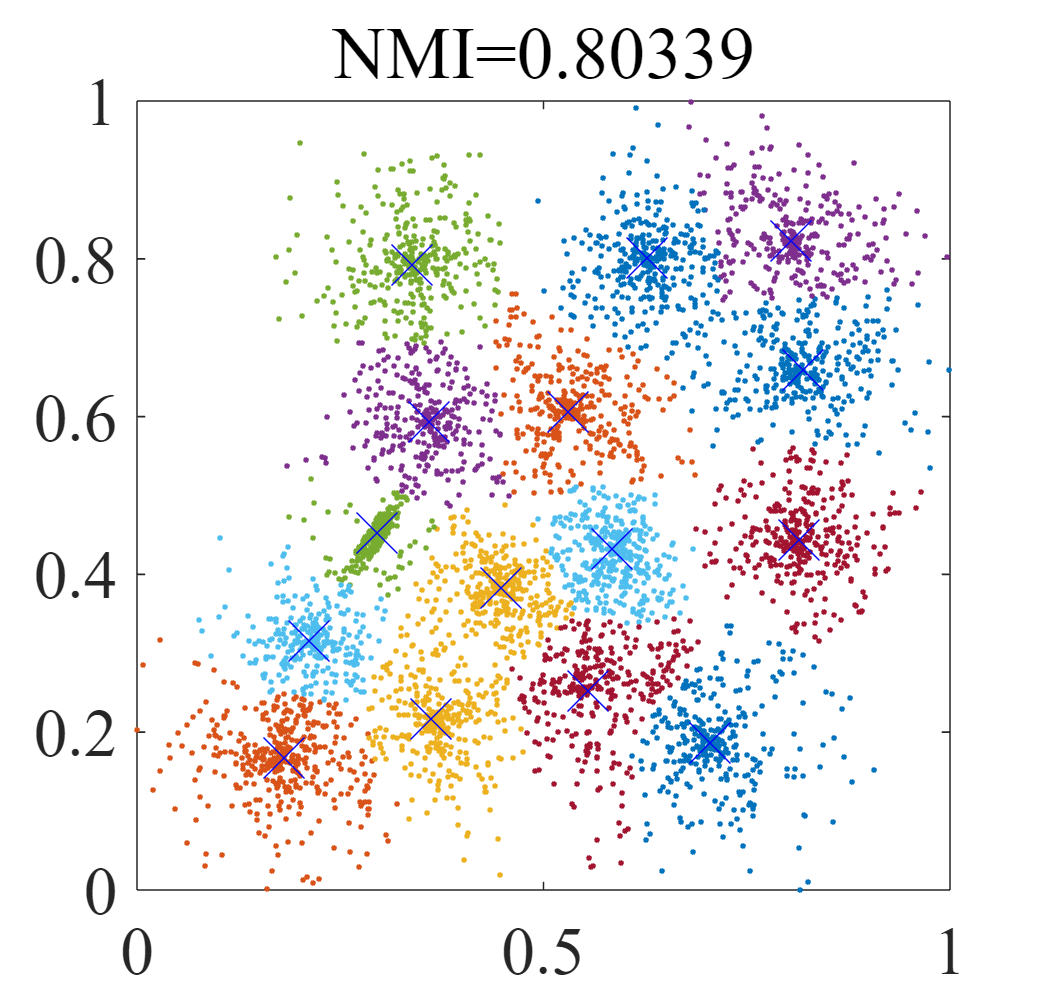

load('s3.mat') % load dateset

data = (data - min(data)).*((max(data) - min(data)).^-1);
data(isnan(data)) = 0.5; % data normalisation
k=size(unique(class),1);

v=0.9;
s=min(size(data,1),10000);
t=100;

psi=64;
Kn=50;
rng(1)

[ndata] = iNNEspace(data,data, psi, t); 
[Tclass,Centre] =DKC(ndata,k,Kn,v,s);
[NMI]=nmi(class,Tclass+1);


visualResults(data,Tclass,Centre,NMI)

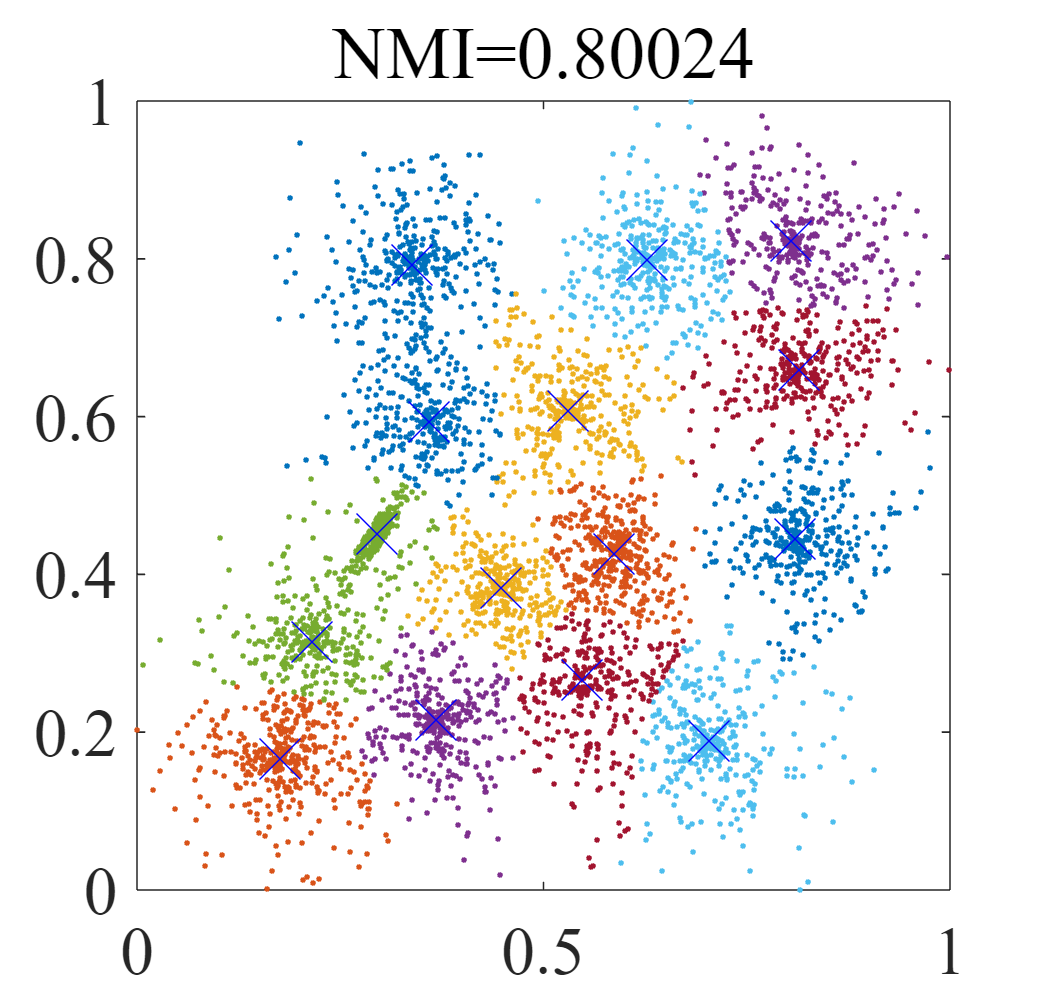

%% GDKC
t=min(400,size(data,1));% sample size for projection
v=0.9;
sig=0.0312;
% 
s=min(size(data,1),10000);
k=size(unique(class),1);
Kn=250;
rng(1)  
[ndata] = sNstr(data,t,sig); % Gaussian features obtained with nystrom
[Tclass,Centre] =DKC(ndata,k,Kn,v,s); % GDKC
[NMI]=nmi(class,Tclass+1);

visualResults(data,Tclass,Centre,NMI)